clc; clear; close all;

% --- Base folder and configuration ---
base_path = 'C:\Users\Markus\Desktop\Data';
tests = {'testA', 'testB', 'testC'};
robot_ids = [6, 8, 11, 15];

% --- Initialize structure ---
AllData = struct();

for t = 1:length(tests)
    test_name = tests{t};
    test_path = fullfile(base_path, test_name);

    for r = 1:length(robot_ids)
        rid = robot_ids(r);
        robot_name = sprintf('SMR%d', rid);
        robot_path = fullfile(test_path, robot_name);
        log_file = fullfile(robot_path, sprintf('log%d', rid));

        % Initialize robot struct
        AllData.(test_name).(robot_name) = struct();

        % === Load raw logX ===
        if isfile(log_file)
            raw = readmatrix(log_file);
            AllData.(test_name).(robot_name).raw = raw;

            AllData.(test_name).(robot_name).x        = raw(:,1);
            AllData.(test_name).(robot_name).y        = raw(:,2);
            AllData.(test_name).(robot_name).theta    = raw(:,3);
            AllData.(test_name).(robot_name).velocity = raw(:,4);
            AllData.(test_name).(robot_name).time     = raw(:,5) - raw(1,5);
        else
            warning('Missing log file: %s', log_file);
            AllData.(test_name).(robot_name).raw = [];
        end

        % === Load full/control log (skip SMR11) ===
        if rid ~= 11
            full_log_path = fullfile(robot_path, sprintf('full_log%d.csv', rid));
            control_log_path = fullfile(robot_path, sprintf('control_log%d.csv', rid));

            if isfile(full_log_path)
                AllData.(test_name).(robot_name).full = readtable(full_log_path);
            else
                AllData.(test_name).(robot_name).full = table();
                warning('Missing full log: %s', full_log_path);
            end

            if isfile(control_log_path)
                AllData.(test_name).(robot_name).control = readtable(control_log_path);
            else
                AllData.(test_name).(robot_name).control = table();
                warning('Missing control log: %s', control_log_path);
            end
        end
    end
end

disp('All logs loaded into AllData structure.');

All logs loaded into AllData structure.


## SMR11

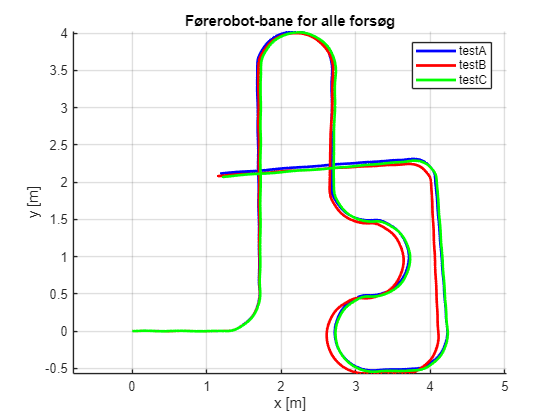

clc;

% --- Settings ---
tests = {'testA', 'testB', 'testC'};
colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green

% --- Extract SMR11 data from AllData ---
data = struct();
for i = 1:3
    tname = tests{i};
    smr = AllData.(tname).SMR11;
    data(i).x = smr.x;
    data(i).y = smr.y;
    data(i).velocity = smr.velocity;
    data(i).time = smr.time;
end

% --- Find overlapping time window ---
end_time = min(arrayfun(@(d) d.time(end), data));
common_time = linspace(0, end_time, 500);

% --- Interpolation ---
x_interp = nan(length(common_time), 3);
y_interp = nan(length(common_time), 3);
velocity_interp = nan(length(common_time), 3);

for i = 1:3
    x_interp(:,i) = interp1(data(i).time, data(i).x, common_time, 'linear', NaN);
    y_interp(:,i) = interp1(data(i).time, data(i).y, common_time, 'linear', NaN);
    velocity_interp(:,i) = interp1(data(i).time, data(i).velocity, common_time, 'linear', NaN);
end

% --- Calculate mean and std ---
mean_x = mean(x_interp, 2, 'omitnan');
mean_y = mean(y_interp, 2, 'omitnan');
std_x = std(x_interp, 0, 2, 'omitnan');
std_y = std(y_interp, 0, 2, 'omitnan');

mean_velocity = mean(velocity_interp, 2, 'omitnan');
std_velocity = std(velocity_interp, 0, 2, 'omitnan');

%% === PLOTS ===

% --- 1. Trajectory plot (individual runs) ---
figure;
hold on;
for i = 1:3
    valid = ~isnan(x_interp(:,i)) & ~isnan(y_interp(:,i));
    plot(x_interp(valid,i), y_interp(valid,i), '-', 'Color', colors{i}, 'LineWidth', 2);
end
xlabel('x [m]'); ylabel('y [m]');
title('Førerobot-bane for alle forsøg');
legend(tests, 'Location', 'Best');
axis equal; grid on;

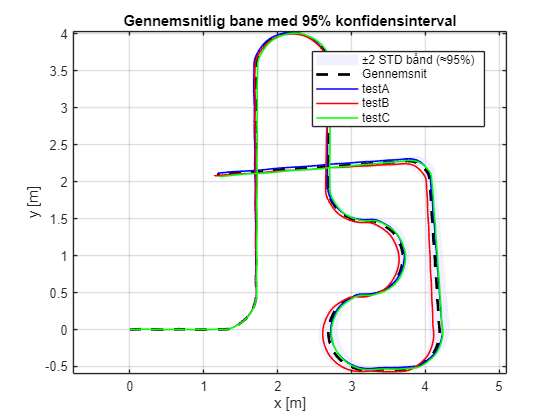


% --- 2. Trajectory mean + 95% confidence band ---
figure;
fill([mean_x + 2*std_x; flipud(mean_x - 2*std_x)], ...
     [mean_y + 2*std_y; flipud(mean_y - 2*std_y)], ...
     [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3); hold on;
plot(mean_x, mean_y, 'k--', 'LineWidth', 2);
for i = 1:3
    valid = ~isnan(x_interp(:,i)) & ~isnan(y_interp(:,i));
    plot(x_interp(valid,i), y_interp(valid,i), '-', 'Color', colors{i}, 'LineWidth', 1.2);
end
xlabel('x [m]'); ylabel('y [m]');
title('Gennemsnitlig bane med 95% konfidensinterval');
legend([{'±2 STD bånd (≈95%)', 'Gennemsnit'}, tests], 'Location', 'Best');
axis equal; grid on;

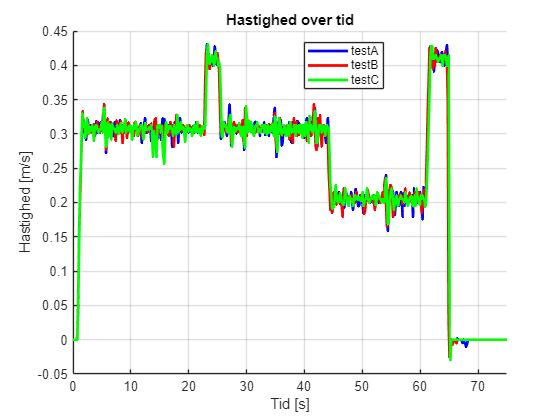


% --- Clip data at 75 seconds ---
clip_idx = common_time <= 75;
common_time_clipped = common_time(clip_idx);
velocity_interp_clipped = velocity_interp(clip_idx, :);
mean_velocity_clipped = mean_velocity(clip_idx);
std_velocity_clipped = std_velocity(clip_idx);

%% --- 3. Velocity over time ---
figure;
hold on;
for i = 1:3
    plot(common_time_clipped, velocity_interp_clipped(:,i), '-', ...
         'Color', colors{i}, 'LineWidth', 2);
end
xlabel('Tid [s]'); ylabel('Hastighed [m/s]');
title('Hastighed over tid');
legend(tests, 'Location', 'Best');
xlim([0 75]);
grid on;

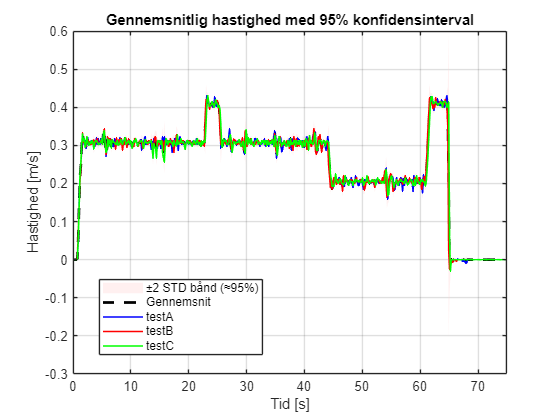


%% --- 4. Velocity mean + 95% CI ---
figure;
fill([common_time_clipped, fliplr(common_time_clipped)], ...
     [mean_velocity_clipped + 2*std_velocity_clipped; ...
      flipud(mean_velocity_clipped - 2*std_velocity_clipped)]', ...
     [1 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.3); hold on;

plot(common_time_clipped, mean_velocity_clipped, 'k--', 'LineWidth', 2);

for i = 1:3
    plot(common_time_clipped, velocity_interp_clipped(:,i), '-', ...
         'Color', colors{i}, 'LineWidth', 1.2);
end

xlabel('Tid [s]'); ylabel('Hastighed [m/s]');
title('Gennemsnitlig hastighed med 95% konfidensinterval');
legend([{'±2 STD bånd (≈95%)', 'Gennemsnit'}, tests], 'Location', 'Best');
xlim([0 75]);
grid on;


clc;

## Odometri

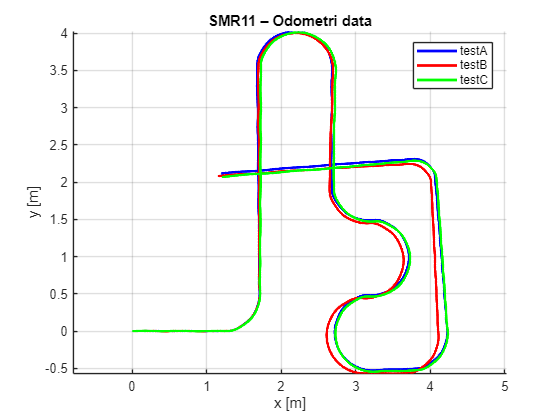

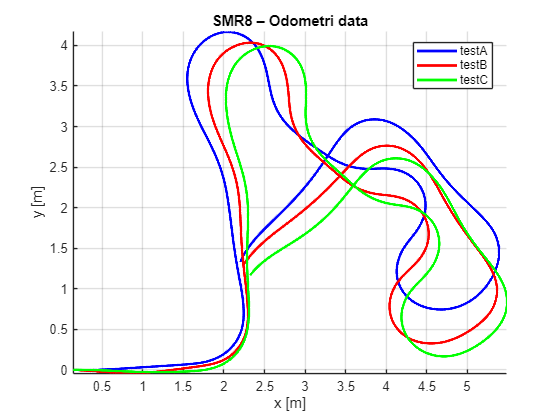

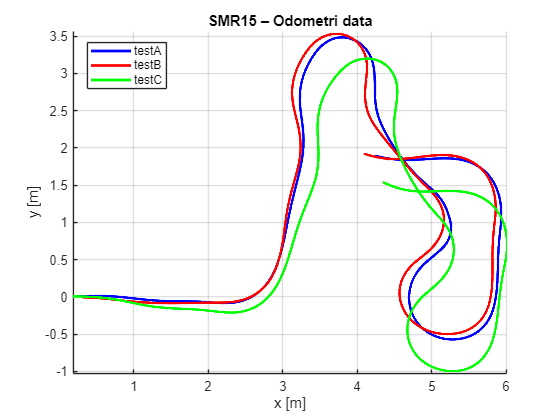

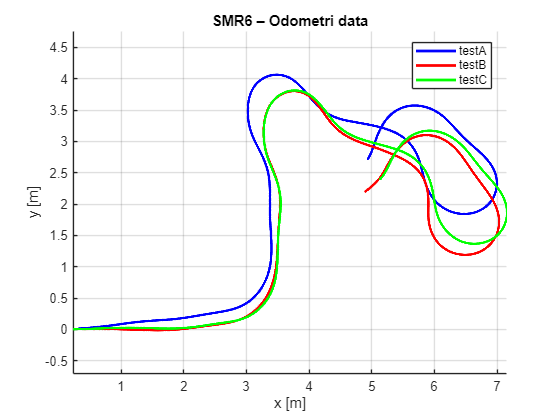

clc;

% --- Configuration ---
tests  = {'testA', 'testB', 'testC'};
robots = {'SMR11', 'SMR8', 'SMR15', 'SMR6'};

% --- Loop over each robot ---
for r = 1:numel(robots)
    robot = robots{r};
    figure('Name', robot, 'NumberTitle', 'off');
    hold on;

    for i = 1:3
        test_name = tests{i};

        % --- Get SMR11 time window ---
        log11 = AllData.(test_name).SMR11.raw;
        t11 = log11(:,5);
        valid11 = ~(log11(:,1) == 0 & log11(:,2) == 0);
        t11 = t11(valid11);
        t_start = t11(1);
        t_cut = t_start + 70;

        % --- Get robot trajectory for this test ---
        raw = AllData.(test_name).(robot).raw;
        x = raw(:,1); y = raw(:,2); t = raw(:,5);
        valid = ~(x == 0 & y == 0);
        x = x(valid); y = y(valid); t = t(valid);

        % --- Clip to SMR11’s time window ---
        in_time = (t >= t_start) & (t <= t_cut);
        x = x(in_time); y = y(in_time);

        % --- Plot ---
        plot(x, y, '-', 'Color', colors{i}, 'LineWidth', 2);
    end

    title(sprintf('%s – Odometri data', robot), 'Interpreter', 'none');
    xlabel('x [m]'); ylabel('y [m]');
    legend(tests, 'Location', 'best');
    axis equal; grid on;
end

## Each Test

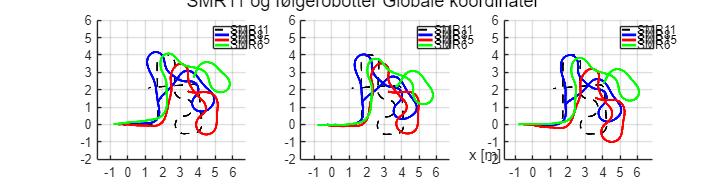

clc;

% --- Setup ---
tests  = {'testA', 'testB', 'testC'};
d_follow = 0.28;  % Distance between robots

% --- Wide landscape figure ---
figure('Units', 'normalized', 'Position', [0.1, 0.4, 0.8, 0.35]);

for i = 1:3
    test_name = tests{i};

    % Load raw logs (logX) for all SMRs
    log11 = AllData.(test_name).SMR11.raw;
    log8  = AllData.(test_name).SMR8.raw;
    log15 = AllData.(test_name).SMR15.raw;
    log6  = AllData.(test_name).SMR6.raw;

    % === SMR11: clean and clip to 70 s ===
    x11_all = log11(:,1); y11_all = log11(:,2); t11_all = log11(:,5); th11_all = log11(:,3);
    valid11 = ~(x11_all == 0 & y11_all == 0);
    x11_valid = x11_all(valid11);
    y11_valid = y11_all(valid11);
    t11_valid = t11_all(valid11);
    th11_valid = th11_all(valid11);
    t_start = t11_valid(1);
    t_cut   = t_start + 70;
    in_range11 = t11_valid <= t_cut;
    x11 = x11_valid(in_range11);
    y11 = y11_valid(in_range11);
    theta11 = th11_valid(1);                  % Use heading from log
    h11 = [cos(theta11); -sin(theta11)];
    origin11 = [x11(1); y11(1)];

    % === SMR8 ===
    valid8 = ~(log8(:,1) == 0 & log8(:,2) == 0);
    x8 = log8(valid8,1); y8 = log8(valid8,2); th8 = log8(valid8,3); t8 = log8(valid8,5);
    in_range8 = (t8 >= t_start) & (t8 <= t_cut);
    x8 = x8(in_range8); y8 = y8(in_range8); th8 = th8(in_range8);

    theta8 = th8(1);                          % Use heading from log
    h8 = [cos(theta8); -sin(theta8)];
    dx8 = x8 - x8(1);
    dy8 = y8 - y8(1);
    x8g = dx8 + origin11(1) - d_follow * h8(1);
    y8g = dy8 + origin11(2) - d_follow * h8(2);

    % === SMR15 ===
    valid15 = ~(log15(:,1) == 0 & log15(:,2) == 0);
    x15 = log15(valid15,1); y15 = log15(valid15,2); th15 = log15(valid15,3); t15 = log15(valid15,5);
    in_range15 = (t15 >= t_start) & (t15 <= t_cut);
    x15 = x15(in_range15); y15 = y15(in_range15); th15 = th15(in_range15);

    theta15 = th15(1);                        % Use heading from log
    h15 = [cos(theta15); -sin(theta15)];
    dx15 = x15 - x15(1);
    dy15 = y15 - y15(1);
    x15g = dx15 + x8g(1) - d_follow * h15(1);
    y15g = dy15 + y8g(1) - d_follow * h15(2);

    % === SMR6 ===
    valid6 = ~(log6(:,1) == 0 & log6(:,2) == 0);
    x6 = log6(valid6,1); y6 = log6(valid6,2); th6 = log6(valid6,3); t6 = log6(valid6,5);
    in_range6 = (t6 >= t_start) & (t6 <= t_cut);
    x6 = x6(in_range6); y6 = y6(in_range6); th6 = th6(in_range6);

    theta6 = th6(1);                          % Use heading from log
    h6 = [cos(theta6); -sin(theta6)];
    dx6 = x6 - x6(1);
    dy6 = y6 - y6(1);
    x6g = dx6 + x15g(1) - d_follow * h6(1);
    y6g = dy6 + y15g(1) - d_follow * h6(2);

    % === Plot ===
    subplot(1,3,i);
    hold on;
    plot(x11,  y11,  'k--', 'LineWidth', 1.5);                 % SMR11
    plot(x8g,  y8g,  '-',  'Color', colors{1}, 'LineWidth', 2);% SMR8
    plot(x15g, y15g, '-',  'Color', colors{2}, 'LineWidth', 2);% SMR15
    plot(x6g,  y6g,  '-',  'Color', colors{3}, 'LineWidth', 2);% SMR6

    title(sprintf('%s – Følgere vs SMR11', test_name), 'Interpreter', 'none');
    xlabel('x [m]'); ylabel('y [m]');
    legend('SMR11', 'SMR8', 'SMR15', 'SMR6', 'Location', 'best');
    axis equal; grid on;
    ylim([-2 6]);
end

sgtitle('SMR11 og følgerobotter Globale koordinater');

## SMR 8

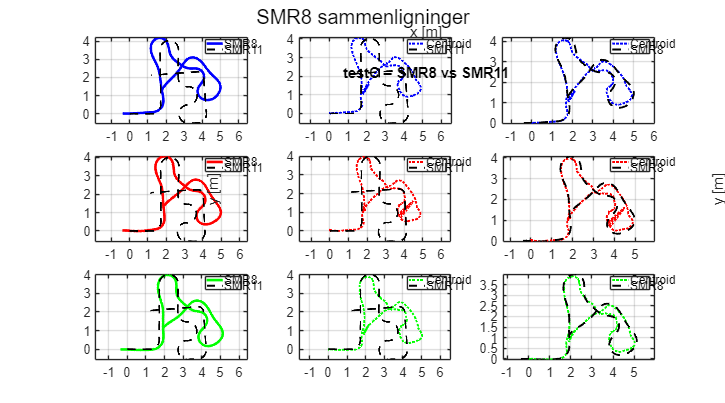

colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green
tests = {'testA', 'testB', 'testC'};

colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green
tests  = {'testA', 'testB', 'testC'};

figure('Name', 'SMR8/Centroid Comparison (3x3)', 'Position', [100, 100, 1800, 1000]);

for i = 1:3
    test_name  = tests{i};
    full_log8  = AllData.(test_name).SMR8.full;
    raw11      = AllData.(test_name).SMR11.raw;

    % --- Clean SMR8 ---
    valid8 = ~(full_log8.Distance == -1 & full_log8.ClusterSize == -1 & ...
               full_log8.Robot_X == 0 & full_log8.Robot_Y == 0);
    full_log8 = full_log8(valid8, :);

    % --- SMR11 reference pose ---
    x11 = raw11(:,1); y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name); continue;
    end
    x_shift = x11(first_valid);
    y_shift = y11(first_valid);

    % --- Use heading at first valid SMR8 pose ---
    valid_start = find(full_log8.Robot_X ~= 0 | full_log8.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start)
        fprintf("Skipping %s: No valid SMR8 motion.\n", test_name); continue;
    end
    theta_rad = deg2rad(full_log8.Robot_Heading_deg(valid_start));
    R = [cos(theta_rad), -sin(theta_rad); sin(theta_rad), cos(theta_rad)];

    % --- Global offset (local centroid at start) ---
    v_local = [full_log8.Centroid_X(valid_start); full_log8.Centroid_Y(valid_start)];
    v_global = R * v_local;

    % --- SMR8 robot global ---
    robot_local   = [full_log8.Robot_X'; full_log8.Robot_Y'];
    robot_rotated = R * robot_local;
    x8_global = robot_rotated(1,:)' - v_global(1) + x_shift;
    y8_global = robot_rotated(2,:)' - v_global(2) + y_shift;

    % --- Centroid global ---
    centroid_local   = [full_log8.Centroid_X'; full_log8.Centroid_Y'];
    centroid_rotated = R * centroid_local;
    x_centroid_global = centroid_rotated(1,:)' - v_global(1) + x_shift;
    y_centroid_global = centroid_rotated(2,:)' - v_global(2) + y_shift;

    % === Subplot Row i ===

    % --- 1. SMR8 vs SMR11 ---
    subplot(3,3,3*(i-1)+1);
    plot(x8_global, y8_global, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x11, y11, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – SMR8 vs SMR11', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('SMR8', 'SMR11', 'Location', 'best');
    axis equal; grid on;

    % --- 2. Centroid vs SMR11 ---
    subplot(3,3,3*(i-1)+2);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x11, y11, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR11', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR11', 'Location', 'best');
    axis equal; grid on;

    % --- 3. Centroid vs SMR8 ---
    subplot(3,3,3*(i-1)+3);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x8_global, y8_global, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR8', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR8', 'Location', 'best');
    axis equal; grid on;
end
sgtitle('SMR8 sammenligninger');

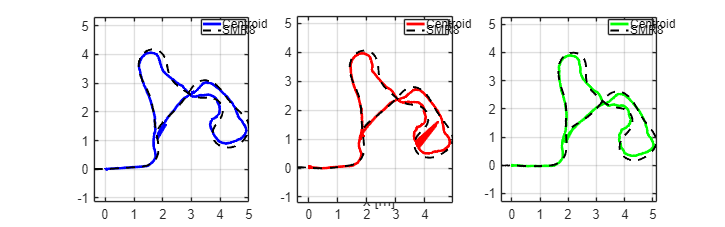


figure('Name', 'Centroid vs SMR8 (per test)', 'Position', [100, 100, 1600, 500]);

for i = 1:3
    test_name = tests{i};
    full_log8 = AllData.(test_name).SMR8.full;
    raw11     = AllData.(test_name).SMR11.raw;

    % --- Remove invalid rows from SMR8 ---
    valid8 = ~(full_log8.Distance == -1 & full_log8.ClusterSize == -1 & ...
               full_log8.Robot_X == 0 & full_log8.Robot_Y == 0);
    full_log8 = full_log8(valid8, :);

    % --- Extract SMR11 shift ---
    x11 = raw11(:,1);
    y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name);
        continue;
    end
    x_shift = x11(first_valid);
    y_shift = y11(first_valid);

    % --- Heading and rotation ---
    valid_start = find(full_log8.Robot_X ~= 0 | full_log8.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start)
        fprintf("Skipping %s: No valid SMR8 motion.\n", test_name);
        continue;
    end
    theta_deg = full_log8.Robot_Heading_deg(valid_start);
    theta_rad = deg2rad(theta_deg);
    R = [cos(theta_rad), -sin(theta_rad); sin(theta_rad), cos(theta_rad)];

    % --- Local → Global shift ---
    v_local = [full_log8.Centroid_X(valid_start); full_log8.Centroid_Y(valid_start)];
    v_global = R * v_local;

    robot_local = [full_log8.Robot_X'; full_log8.Robot_Y'];
    robot_rotated = R * robot_local;
    x8 = robot_rotated(1,:)' - v_global(1) + x_shift;
    y8 = robot_rotated(2,:)' - v_global(2) + y_shift;

    centroid_local = [full_log8.Centroid_X'; full_log8.Centroid_Y'];
    centroid_rotated = R * centroid_local;
    x_centroid = centroid_rotated(1,:)' - v_global(1) + x_shift;
    y_centroid = centroid_rotated(2,:)' - v_global(2) + y_shift;

    % === Plot Centroid vs SMR8 ===
    subplot(1,3,i);
    plot(x_centroid, y_centroid, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x8, y8, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR8', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR8', 'Location', 'Best');
    axis equal; grid on;
end

## SMR15

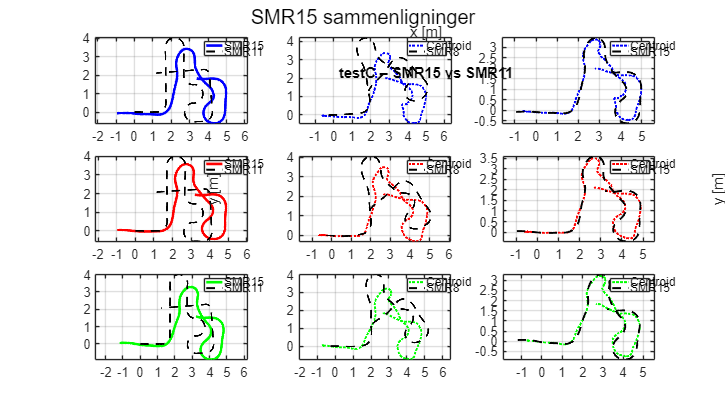

colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green
tests  = {'testA', 'testB', 'testC'};
d_follow = 0.28;  % Robot spacing

figure('Name', 'SMR15/Centroid Comparison (3x3)', 'Position', [100, 100, 1800, 1000]);

sgtitle('SMR15 sammenligninger');

for i = 1:3
    test_name  = tests{i};
    full_log15 = AllData.(test_name).SMR15.full;
    raw8       = AllData.(test_name).SMR8.raw;
    raw11      = AllData.(test_name).SMR11.raw;

    % --- Clean SMR15 ---
    valid15 = ~(full_log15.Distance == -1 & full_log15.ClusterSize == -1 & ...
                full_log15.Robot_X == 0 & full_log15.Robot_Y == 0);
    full_log15 = full_log15(valid15, :);

    % --- SMR11 reference pose ---
    x11 = raw11(:,1); y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name); continue;
    end
    origin11 = [x11(first_valid); y11(first_valid)];

    % --- Heading of SMR8 (leader of SMR15) ---
    valid_start_8 = find(raw8(:,1) ~= 0 | raw8(:,2) ~= 0, 1, 'first');
    theta8 = raw8(valid_start_8, 3);
    h8 = [cos(theta8); -sin(theta8)];

    % --- Heading of SMR15 ---
    valid_start_15 = find(full_log15.Robot_X ~= 0 | full_log15.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start_15)
        fprintf("Skipping %s: No valid SMR15 motion.\n", test_name); continue;
    end
    theta15 = deg2rad(full_log15.Robot_Heading_deg(valid_start_15));
    R15 = [cos(theta15), -sin(theta15); sin(theta15), cos(theta15)];

    % --- Shift origin from SMR8 ---
    r15_local_start = [full_log15.Robot_X(valid_start_15); full_log15.Robot_Y(valid_start_15)];
    v_local = [full_log15.Centroid_X(valid_start_15); full_log15.Centroid_Y(valid_start_15)];
    v_global = R15 * v_local;

    % --- Compute SMR8 global anchor ---
    r8_local_start = [raw8(valid_start_8,1); raw8(valid_start_8,2)];
    r8_global_start = R15 * r8_local_start;
    anchor8 = origin11 - d_follow * h8;
    origin15 = anchor8 + r8_global_start - v_global;

    % --- Robot trajectory ---
    robot_local = [full_log15.Robot_X'; full_log15.Robot_Y'];
    robot_rotated = R15 * robot_local;
    x15_global = robot_rotated(1,:)' - v_global(1) + origin15(1);
    y15_global = robot_rotated(2,:)' - v_global(2) + origin15(2);

    % --- Centroid trajectory ---
    centroid_local = [full_log15.Centroid_X'; full_log15.Centroid_Y'];
    centroid_rotated = R15 * centroid_local;
    x_centroid_global = centroid_rotated(1,:)' - v_global(1) + origin15(1);
    y_centroid_global = centroid_rotated(2,:)' - v_global(2) + origin15(2);

    % --- SMR8 global ---
    r8 = R15 * [raw8(:,1)'; raw8(:,2)'];
    x8_global = r8(1,:)' - r8_global_start(1) + anchor8(1);
    y8_global = r8(2,:)' - r8_global_start(2) + anchor8(2);

    % === Subplot Row i ===

    % --- 1. SMR15 vs SMR11 ---
    subplot(3,3,3*(i-1)+1);
    plot(x15_global, y15_global, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x11, y11, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – SMR15 vs SMR11', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('SMR15', 'SMR11', 'Location', 'best');
    axis equal; grid on;

    % --- 2. Centroid vs SMR8 ---
    subplot(3,3,3*(i-1)+2);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x8_global, y8_global, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR8', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR8', 'Location', 'best');
    axis equal; grid on;

    % --- 3. Centroid vs SMR15 ---
    subplot(3,3,3*(i-1)+3);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x15_global, y15_global, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR15', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR15', 'Location', 'best');
    axis equal; grid on;
end

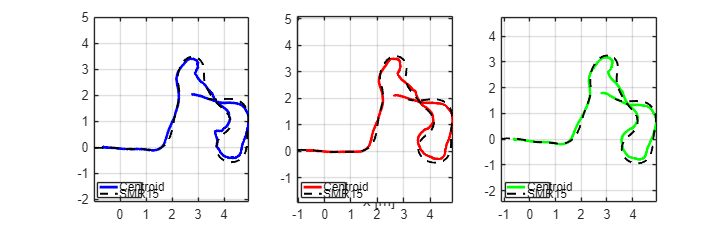




figure('Name', 'Centroid vs SMR15 (per test)', 'Position', [100, 100, 1600, 500]);
for i = 1:3
    test_name   = tests{i};
    full_log15  = AllData.(test_name).SMR15.full;
    full_log8   = AllData.(test_name).SMR8.full;
    raw11       = AllData.(test_name).SMR11.raw;

    % --- Remove invalid rows from SMR15 ---
    valid15 = ~(full_log15.Distance == -1 & full_log15.ClusterSize == -1 & ...
                full_log15.Robot_X == 0 & full_log15.Robot_Y == 0);
    full_log15 = full_log15(valid15, :);

    % --- Remove invalid rows from SMR8 ---
    valid8 = ~(full_log8.Robot_X == 0 & full_log8.Robot_Y == 0);
    full_log8 = full_log8(valid8, :);

    % --- Reference origin from SMR11 ---
    x11 = raw11(:,1);
    y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name);
        continue;
    end
    x_shift_11 = x11(first_valid);
    y_shift_11 = y11(first_valid);

    % --- Transform SMR8 to global to use as anchor for SMR15 ---
    valid_start_8 = find(full_log8.Robot_X ~= 0 | full_log8.Robot_Y ~= 0, 1, 'first');
    theta8 = deg2rad(full_log8.Robot_Heading_deg(valid_start_8));
    R8 = [cos(theta8), -sin(theta8); sin(theta8), cos(theta8)];
    r8_start = R8 * [full_log8.Robot_X(valid_start_8); full_log8.Robot_Y(valid_start_8)];
    c8_start = R8 * [full_log8.Centroid_X(valid_start_8); full_log8.Centroid_Y(valid_start_8)];
    anchor8 = r8_start - c8_start + [x_shift_11; y_shift_11];

    % --- Heading + rotation for SMR15 ---
    valid_start_15 = find(full_log15.Robot_X ~= 0 | full_log15.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start_15)
        fprintf("Skipping %s: No valid SMR15 motion.\n", test_name);
        continue;
    end
    theta15 = deg2rad(full_log15.Robot_Heading_deg(valid_start_15));
    R15 = [cos(theta15), -sin(theta15); sin(theta15), cos(theta15)];
    h15 = [cos(theta15); -sin(theta15)];

    % --- Offset anchor for SMR15 behind SMR8 ---
    anchor15 = anchor8 - d_follow * h15;

    % --- Centroid offset in global frame ---
    c15_local = [full_log15.Centroid_X(valid_start_15); full_log15.Centroid_Y(valid_start_15)];
    c15_global_offset = R15 * c15_local;

    % --- SMR15 robot global ---
    robot_local = [full_log15.Robot_X'; full_log15.Robot_Y'];
    robot_rotated = R15 * robot_local;
    x15 = robot_rotated(1,:)' - c15_global_offset(1) + anchor15(1);
    y15 = robot_rotated(2,:)' - c15_global_offset(2) + anchor15(2);

    % --- Centroid global ---
    centroid_local = [full_log15.Centroid_X'; full_log15.Centroid_Y'];
    centroid_rotated = R15 * centroid_local;
    x_centroid = centroid_rotated(1,:)' - c15_global_offset(1) + anchor15(1);
    y_centroid = centroid_rotated(2,:)' - c15_global_offset(2) + anchor15(2);

    % === Plot Centroid vs SMR15 ===
    subplot(1,3,i);
    plot(x_centroid, y_centroid, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x15, y15, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR15', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR15', 'Location', 'Best');
    axis equal; grid on;
end

## SMR 6

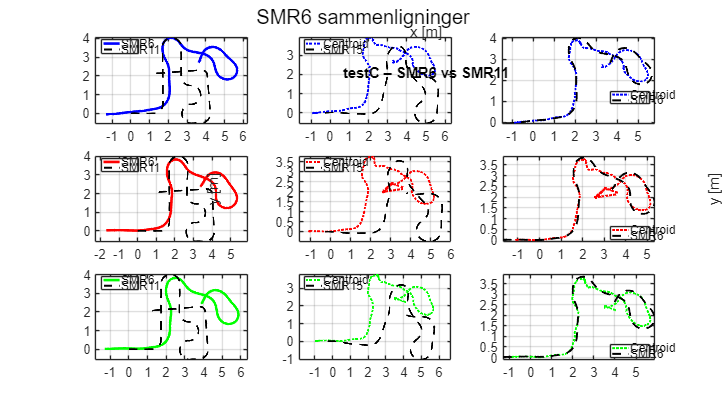

colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green
tests  = {'testA', 'testB', 'testC'};
d_follow = 0.28;  % Distance between robots

figure('Name', 'SMR6/Centroid Comparison (3x3)', 'Position', [100, 100, 1800, 1000]);
sgtitle('SMR6 sammenligninger');
for i = 1:3
    test_name   = tests{i};
    full_log6   = AllData.(test_name).SMR6.full;
    raw15       = AllData.(test_name).SMR15.raw;
    raw11       = AllData.(test_name).SMR11.raw;

    % --- Clean SMR6 ---
    valid6 = ~(full_log6.Distance == -1 & full_log6.ClusterSize == -1 & ...
               full_log6.Robot_X == 0 & full_log6.Robot_Y == 0);
    full_log6 = full_log6(valid6, :);

    % --- SMR11 reference pose ---
    x11 = raw11(:,1); y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name); continue;
    end
    origin11 = [x11(first_valid); y11(first_valid)];

    % --- Heading of SMR15 (leader of SMR6) ---
    valid_start_15 = find(raw15(:,1) ~= 0 | raw15(:,2) ~= 0, 1, 'first');
    theta15 = raw15(valid_start_15, 3);
    h15 = [cos(theta15); -sin(theta15)];

    % --- Heading of SMR6 ---
    valid_start_6 = find(full_log6.Robot_X ~= 0 | full_log6.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start_6)
        fprintf("Skipping %s: No valid SMR6 motion.\n", test_name); continue;
    end
    theta6 = deg2rad(full_log6.Robot_Heading_deg(valid_start_6));
    R6 = [cos(theta6), -sin(theta6); sin(theta6), cos(theta6)];

    % --- Shift origin from SMR15 ---
    r6_local_start = [full_log6.Robot_X(valid_start_6); full_log6.Robot_Y(valid_start_6)];
    v_local = [full_log6.Centroid_X(valid_start_6); full_log6.Centroid_Y(valid_start_6)];
    v_global = R6 * v_local;

    % --- Compute global anchor (based on SMR15) ---
    r15_local_start = [raw15(valid_start_15,1); raw15(valid_start_15,2)];
    r15_global_start = R6 * r15_local_start;
    anchor15 = origin11 - d_follow * h15;
    origin6 = anchor15 - d_follow * h15 + r15_global_start - v_global;

    % --- Robot 6 global trajectory ---
    robot_local = [full_log6.Robot_X'; full_log6.Robot_Y'];
    robot_rotated = R6 * robot_local;
    x6_global = robot_rotated(1,:)' - v_global(1) + origin6(1);
    y6_global = robot_rotated(2,:)' - v_global(2) + origin6(2);

    % --- Centroid global trajectory ---
    centroid_local   = [full_log6.Centroid_X'; full_log6.Centroid_Y'];
    centroid_rotated = R6 * centroid_local;
    x_centroid_global = centroid_rotated(1,:)' - v_global(1) + origin6(1);
    y_centroid_global = centroid_rotated(2,:)' - v_global(2) + origin6(2);

    % --- SMR15 global ---
    r15 = R6 * [raw15(:,1)'; raw15(:,2)'];
    x15_global = r15(1,:)' - r15_global_start(1) + anchor15(1);
    y15_global = r15(2,:)' - r15_global_start(2) + anchor15(2);

    % === Subplot Row i ===

    % --- 1. SMR6 vs SMR11 ---
    subplot(3,3,3*(i-1)+1);
    plot(x6_global, y6_global, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x11, y11, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – SMR6 vs SMR11', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('SMR6', 'SMR11', 'Location', 'best');
    axis equal; grid on;

    % --- 2. Centroid vs SMR15 ---
    subplot(3,3,3*(i-1)+2);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x15_global, y15_global, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR15', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR15', 'Location', 'best');
    axis equal; grid on;

    % --- 3. Centroid vs SMR6 ---
    subplot(3,3,3*(i-1)+3);
    plot(x_centroid_global, y_centroid_global, ':', 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    plot(x6_global, y6_global, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR6', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR6', 'Location', 'best');
    axis equal; grid on;
end

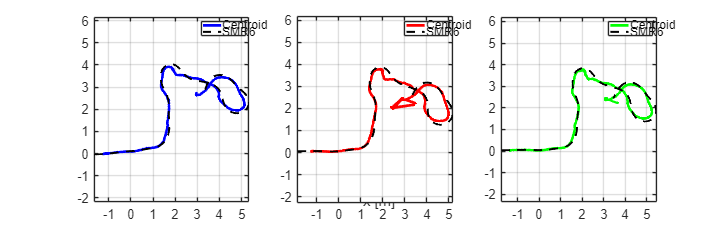



colors = {[0 0 1], [1 0 0], [0 1 0]};  % Blue, Red, Green
tests = {'testA', 'testB', 'testC'};
d_follow = 0.28;

figure('Name', 'Centroid vs SMR6 (per test)', 'Position', [100, 100, 1600, 500]);

for i = 1:3
    test_name   = tests{i};
    full_log6   = AllData.(test_name).SMR6.full;
    full_log15  = AllData.(test_name).SMR15.full;
    full_log8   = AllData.(test_name).SMR8.full;
    raw11       = AllData.(test_name).SMR11.raw;

    % --- Remove invalid rows ---
    valid6 = ~(full_log6.Distance == -1 & full_log6.ClusterSize == -1 & ...
               full_log6.Robot_X == 0 & full_log6.Robot_Y == 0);
    full_log6 = full_log6(valid6, :);

    valid15 = ~(full_log15.Robot_X == 0 & full_log15.Robot_Y == 0);
    full_log15 = full_log15(valid15, :);

    valid8 = ~(full_log8.Robot_X == 0 & full_log8.Robot_Y == 0);
    full_log8 = full_log8(valid8, :);

    % --- SMR11 origin shift ---
    x11 = raw11(:,1);
    y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    first_valid = find(valid11, 1, 'first');
    if isempty(first_valid)
        fprintf("Skipping %s: No valid SMR11 data.\n", test_name);
        continue;
    end
    x_shift_11 = x11(first_valid);
    y_shift_11 = y11(first_valid);

    % --- Transform SMR8 to global ---
    valid_start_8 = find(full_log8.Robot_X ~= 0 | full_log8.Robot_Y ~= 0, 1, 'first');
    theta8 = deg2rad(full_log8.Robot_Heading_deg(valid_start_8));
    R8 = [cos(theta8), -sin(theta8); sin(theta8), cos(theta8)];
    r8_start = R8 * [full_log8.Robot_X(valid_start_8); full_log8.Robot_Y(valid_start_8)];
    c8_start = R8 * [full_log8.Centroid_X(valid_start_8); full_log8.Centroid_Y(valid_start_8)];
    anchor8 = r8_start - c8_start + [x_shift_11; y_shift_11];

    % --- Transform SMR15 to global ---
    valid_start_15 = find(full_log15.Robot_X ~= 0 | full_log15.Robot_Y ~= 0, 1, 'first');
    theta15 = deg2rad(full_log15.Robot_Heading_deg(valid_start_15));
    R15 = [cos(theta15), -sin(theta15); sin(theta15), cos(theta15)];
    h15 = [cos(theta15); -sin(theta15)];
    r15_start = R15 * [full_log15.Robot_X(valid_start_15); full_log15.Robot_Y(valid_start_15)];
    c15_start = R15 * [full_log15.Centroid_X(valid_start_15); full_log15.Centroid_Y(valid_start_15)];
    anchor15 = r15_start - c15_start + anchor8 - d_follow * h15;

    % --- Transform SMR6 to global ---
    valid_start_6 = find(full_log6.Robot_X ~= 0 | full_log6.Robot_Y ~= 0, 1, 'first');
    if isempty(valid_start_6)
        fprintf("Skipping %s: No valid SMR6 motion.\n", test_name);
        continue;
    end
    theta6 = deg2rad(full_log6.Robot_Heading_deg(valid_start_6));
    R6 = [cos(theta6), -sin(theta6); sin(theta6), cos(theta6)];
    h6 = [cos(theta6); -sin(theta6)];

    % --- Offset anchor for SMR6 ---
    c6_start = R6 * [full_log6.Centroid_X(valid_start_6); full_log6.Centroid_Y(valid_start_6)];
    anchor6 = anchor15 - d_follow * h6;

    % --- Robot 6 global ---
    robot_local = [full_log6.Robot_X'; full_log6.Robot_Y'];
    robot_rotated = R6 * robot_local;
    x6 = robot_rotated(1,:)' - c6_start(1) + anchor6(1);
    y6 = robot_rotated(2,:)' - c6_start(2) + anchor6(2);

    % --- Centroid global ---
    centroid_local = [full_log6.Centroid_X'; full_log6.Centroid_Y'];
    centroid_rotated = R6 * centroid_local;
    x_centroid = centroid_rotated(1,:)' - c6_start(1) + anchor6(1);
    y_centroid = centroid_rotated(2,:)' - c6_start(2) + anchor6(2);

    % === Plot Centroid vs SMR6 ===
    subplot(1,3,i);
    plot(x_centroid, y_centroid, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    plot(x6, y6, 'k--', 'LineWidth', 1.5);
    title(sprintf('%s – Centroid vs SMR6', test_name));
    xlabel('x [m]'); ylabel('y [m]');
    legend('Centroid', 'SMR6', 'Location', 'Best');
    axis equal; grid on;
end

## Statistics

### SMR8

% === Initialize tables ===
results_SMR8_to_11     = [];
results_Centroid_to_11 = [];
results_SMR8_to_Centroid = [];
tests = {'testA', 'testB', 'testC'};

for i = 1:3
    test_name = tests{i};
    log8  = AllData.(test_name).SMR8.full;
    raw11 = AllData.(test_name).SMR11.raw;

    % --- Clean up invalid rows ---
    valid8 = ~(log8.Distance == -1 | log8.ClusterSize == -1 | ...
              (log8.Robot_X == 0 & log8.Robot_Y == 0));
    log8 = log8(valid8, :);

    x11 = raw11(:,1); y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    x11 = x11(valid11); y11 = y11(valid11);

    % === Transform SMR8 and Centroid to global ===
    idx8 = find(log8.Robot_X ~= 0 | log8.Robot_Y ~= 0, 1);
    theta8 = deg2rad(log8.Robot_Heading_deg(idx8));
    R8 = [cos(theta8), -sin(theta8); sin(theta8), cos(theta8)];
    v8 = R8 * [log8.Centroid_X(idx8); log8.Centroid_Y(idx8)];

    r8 = R8 * [log8.Robot_X'; log8.Robot_Y'];
    x8_global = r8(1,:)' - v8(1);
    y8_global = r8(2,:)' - v8(2);

    c = R8 * [log8.Centroid_X'; log8.Centroid_Y'];
    xC = c(1,:)' - v8(1);
    yC = c(2,:)' - v8(2);

    % === Interpolation ===
    N = min([length(x8_global), length(xC), length(x11)]);
    t_ref = linspace(0, 1, N);

    x8i  = interp1(linspace(0,1,length(x8_global)), x8_global, t_ref, 'linear', 'extrap');
    y8i  = interp1(linspace(0,1,length(y8_global)), y8_global, t_ref, 'linear', 'extrap');
    xCi  = interp1(linspace(0,1,length(xC)),        xC,        t_ref, 'linear', 'extrap');
    yCi  = interp1(linspace(0,1,length(yC)),        yC,        t_ref, 'linear', 'extrap');
    x11i = interp1(linspace(0,1,length(x11)),       x11,       t_ref, 'linear', 'extrap');
    y11i = interp1(linspace(0,1,length(y11)),       y11,       t_ref, 'linear', 'extrap');

    % === Error functions ===
    err = @(x1, y1, x2, y2) sqrt((x1 - x2).^2 + (y1 - y2).^2);
    stats = @(e) [mean(e), std(e), min(e), max(e), median(e), quantile(e,0.25), quantile(e,0.75)];

    % --- 1: SMR8 → SMR11 ---
    e1 = err(x8i, y8i, x11i, y11i);
    results_SMR8_to_11 = [results_SMR8_to_11; [{test_name}, num2cell(round(stats(e1), 3))]];

    % --- 2: Centroid → SMR11 ---
    e2 = err(xCi, yCi, x11i, y11i);
    results_Centroid_to_11 = [results_Centroid_to_11; [{test_name}, num2cell(round(stats(e2), 3))]];

    % --- 3: SMR8 → Centroid ---
    e3 = err(x8i, y8i, xCi, yCi);
    results_SMR8_to_Centroid = [results_SMR8_to_Centroid; [{test_name}, num2cell(round(stats(e3), 3))]];
end

% === Convert to tables ===
colNames = {'Test', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr', 'Q1', 'Q3'};
results_SMR8_to_11       = cell2table(results_SMR8_to_11,       'VariableNames', colNames);
results_Centroid_to_11   = cell2table(results_Centroid_to_11,   'VariableNames', colNames);
results_SMR8_to_Centroid = cell2table(results_SMR8_to_Centroid, 'VariableNames', colNames);

% === Append Gennemsnit row ===
append_avg = @(T) [T; [{{'Gennemsnit'}}, num2cell(round(mean(table2array(T(:,2:end))), 3))]];
results_SMR8_to_11       = append_avg(results_SMR8_to_11);
results_Centroid_to_11   = append_avg(results_Centroid_to_11);
results_SMR8_to_Centroid = append_avg(results_SMR8_to_Centroid);

% === Display ===
disp('=== Distance Error: SMR8 → SMR11 ===');

=== Distance Error: SMR8 → SMR11 ===


disp(results_SMR8_to_11);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     1.341     0.594     0.357     2.811       1.257      0.893    1.834
    {'testB'     }     2.175     0.962     0.107     3.853       2.184      1.364     2.99
    {'testC'     }     1.856     0.688     0.347     3.181       1.955      1.264    2.402
    {'Gennemsnit'}     1.791     0.748      0.27     3.282       1.799      1.174    2.409




disp('=== Distance Error: Centroid → SMR11 ===');

=== Distance Error: Centroid → SMR11 ===


disp(results_Centroid_to_11);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     1.075     0.505       0       2.201       1.039      0.689    1.448
    {'testB'     }     1.945     0.833       0       3.473       1.937      1.212     2.75
    {'testC'     }     1.521     0.654       0       2.871       1.456      1.128    2.015
    {'Gennemsnit'}     1.514     0.664       0       2.848       1.477       1.01    2.071




disp('=== Distance Error: SMR8 → Centroid ===');

=== Distance Error: SMR8 → Centroid ===


disp(results_SMR8_to_Centroid);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     0.514     0.114     0.184     0.748       0.539       0.47    0.585
    {'testB'     }     0.502     0.126     0.185     0.755       0.532      0.467    0.583
    {'testC'     }     0.533     0.082     0.273     0.756       0.546      0.476    0.581
    {'Gennemsnit'}     0.516     0.107     0.214     0.753       0.539      0.471    0.583



### SMR 15

% === Initialize tables ===
results_SMR15_to_11       = [];
results_Centroid_to_8     = [];
results_SMR15_to_Centroid = [];
tests = {'testA', 'testB', 'testC'};

for i = 1:3
    test_name = tests{i};
    log15 = AllData.(test_name).SMR15.full;
    raw11 = AllData.(test_name).SMR11.raw;
    raw8  = AllData.(test_name).SMR8.raw;

    % --- Clean up --- 
    valid15 = ~(log15.Distance == -1 | log15.ClusterSize == -1 | ...
               (log15.Robot_X == 0 & log15.Robot_Y == 0) | ...
               (log15.Centroid_X == -1 | log15.Centroid_X == -1000 | ...
                log15.Centroid_Y == -1 | log15.Centroid_Y == -1000));
    log15 = log15(valid15, :);

    % Get raw positions
    x11 = raw11(:,1); y11 = raw11(:,2);
    x8  = raw8(:,1);  y8  = raw8(:,2);

    % Clean x11/y11 and x8/y8 in pairs
    valid11 = ~(x11 == 0 & y11 == 0);
    x11 = x11(valid11); y11 = y11(valid11);

    valid8 = ~(x8 == 0 & y8 == 0);
    x8 = x8(valid8); y8 = y8(valid8);

    % --- Transform SMR15 and centroid to global ---
    idx15 = find(log15.Robot_X ~= 0 | log15.Robot_Y ~= 0, 1);
    theta15 = deg2rad(log15.Robot_Heading_deg(idx15));
    R15 = [cos(theta15), -sin(theta15); sin(theta15), cos(theta15)];
    v15 = R15 * [log15.Centroid_X(idx15); log15.Centroid_Y(idx15)];

    r15 = R15 * [log15.Robot_X'; log15.Robot_Y'];
    x15_global = r15(1,:)' - v15(1);
    y15_global = r15(2,:)' - v15(2);

    c = R15 * [log15.Centroid_X'; log15.Centroid_Y'];
    xC = c(1,:)' - v15(1);
    yC = c(2,:)' - v15(2);

    % --- Interpolation ---
    N = 500;
    t_ref = linspace(0, 1, N);
    interp = @(x) interp1(linspace(0,1,length(x)), x, t_ref, 'linear', 'extrap');

    x15i = interp(x15_global); y15i = interp(y15_global);
    xCi  = interp(xC);          yCi  = interp(yC);
    x11i = interp(x11);         y11i = interp(y11);
    x8i  = interp(x8);          y8i  = interp(y8);

    % --- Error functions ---
    err = @(x1, y1, x2, y2) sqrt((x1 - x2).^2 + (y1 - y2).^2);
    stats = @(e) [mean(e), std(e), min(e), max(e), median(e), quantile(e,0.25), quantile(e,0.75)];

    % --- 1: SMR15 → SMR11 ---
    e1 = err(x15i, y15i, x11i, y11i);
    results_SMR15_to_11 = [results_SMR15_to_11; [{test_name}, num2cell(round(stats(e1), 3))]];

    % --- 2: Centroid (SMR15) → SMR8 ---
    e2 = err(xCi, yCi, x8i, y8i);
    results_Centroid_to_8 = [results_Centroid_to_8; [{test_name}, num2cell(round(stats(e2), 3))]];

    % --- 3: SMR15 → Centroid (SMR15) ---
    e3 = err(x15i, y15i, xCi, yCi);
    results_SMR15_to_Centroid = [results_SMR15_to_Centroid; [{test_name}, num2cell(round(stats(e3), 3))]];
end

% === Convert to tables ===
colNames = {'Test', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr', 'Q1', 'Q3'};
results_SMR15_to_11       = cell2table(results_SMR15_to_11,       'VariableNames', colNames);
results_Centroid_to_8     = cell2table(results_Centroid_to_8,     'VariableNames', colNames);
results_SMR15_to_Centroid = cell2table(results_SMR15_to_Centroid, 'VariableNames', colNames);

% === Append 'Gennemsnit' row ===
append_avg = @(T) [T; [{ 'Gennemsnit' }, num2cell(round(mean(table2array(T(:,2:end))), 3))]];
results_SMR15_to_11       = append_avg(results_SMR15_to_11);
results_Centroid_to_8     = append_avg(results_Centroid_to_8);
results_SMR15_to_Centroid = append_avg(results_SMR15_to_Centroid);


% === Display all ===
disp('=== Distance Error: SMR15 → SMR11 ===');

=== Distance Error: SMR15 → SMR11 ===


disp(results_SMR15_to_11);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     2.396     1.167     0.227     4.554       2.475      1.544    3.316
    {'testB'     }     2.875      1.37     0.327     4.779       2.994        1.8    4.111
    {'testC'     }     2.536     1.269     0.291     4.749       2.557      1.454    3.475
    {'Gennemsnit'}     2.602     1.269     0.282     4.694       2.675      1.599    3.634




disp('=== Distance Error: Centroid (SMR15) → SMR8 ===');

=== Distance Error: Centroid (SMR15) → SMR8 ===


disp(results_Centroid_to_8);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     1.618     1.189       0       3.571        1.47      0.476    2.878
    {'testB'     }     1.741     1.079       0       3.281       1.679      0.807    2.893
    {'testC'     }     1.301     1.037       0       3.039       1.114      0.294    2.426
    {'Gennemsnit'}     1.553     1.102       0       3.297       1.421      0.526    2.732




disp('=== Distance Error: SMR15 → Centroid (SMR15) ===');

=== Distance Error: SMR15 → Centroid (SMR15) ===


disp(results_SMR15_to_Centroid);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     0.493     0.084      0.27      0.68       0.505      0.448    0.555
    {'testB'     }     0.487     0.092     0.266     0.696       0.495       0.44    0.552
    {'testC'     }     0.501     0.072     0.283     0.694       0.506       0.45    0.555
    {'Gennemsnit'}     0.494     0.083     0.273      0.69       0.502      0.446    0.554



### SMR6

% === Initialize tables ===
results_SMR6_to_15 = [];
results_Centroid_to_15 = [];
results_SMR6_to_Centroid = [];
tests = {'testA', 'testB', 'testC'};

for i = 1:3
    test_name = tests{i};
    log6  = AllData.(test_name).SMR6.full;
    raw15 = AllData.(test_name).SMR15.raw;

    % --- Clean up ---
    valid6 = ~(log6.Distance == -1 | log6.ClusterSize == -1 | ...
              (log6.Robot_X == 0 & log6.Robot_Y == 0) | ...
              (log6.Centroid_X == -1 | log6.Centroid_X == -1000 | ...
               log6.Centroid_Y == -1 | log6.Centroid_Y == -1000));
    log6 = log6(valid6, :);

    x15 = raw15(:,1); y15 = raw15(:,2);
    valid15 = ~(x15 == 0 & y15 == 0);
    x15 = x15(valid15); y15 = y15(valid15);

    % === Transform SMR6 and Centroid to global ===
    idx6 = find(log6.Robot_X ~= 0 | log6.Robot_Y ~= 0, 1);
    theta6 = deg2rad(log6.Robot_Heading_deg(idx6));
    R6 = [cos(theta6), -sin(theta6); sin(theta6), cos(theta6)];
    v6 = R6 * [log6.Centroid_X(idx6); log6.Centroid_Y(idx6)];

    r6 = R6 * [log6.Robot_X'; log6.Robot_Y'];
    x6_global = r6(1,:)' - v6(1);
    y6_global = r6(2,:)' - v6(2);

    c = R6 * [log6.Centroid_X'; log6.Centroid_Y'];
    xC = c(1,:)' - v6(1);
    yC = c(2,:)' - v6(2);

    % === Interpolation ===
    N = 500;
    t_ref = linspace(0, 1, N);
    interp = @(x) interp1(linspace(0,1,length(x)), x, t_ref, 'linear', 'extrap');

    x6i = interp(x6_global); y6i = interp(y6_global);
    xCi = interp(xC);        yCi = interp(yC);
    x15i = interp(x15);      y15i = interp(y15);

    % === Error metrics ===
    err = @(x1, y1, x2, y2) sqrt((x1 - x2).^2 + (y1 - y2).^2);
    stats = @(e) [mean(e), std(e), min(e), max(e), median(e), quantile(e,0.25), quantile(e,0.75)];

    % --- 1. SMR6 → SMR15 ---
    e1 = err(x6i, y6i, x15i, y15i);
    results_SMR6_to_15 = [results_SMR6_to_15; [{test_name}, num2cell(round(stats(e1), 3))]];

    % --- 2. Centroid → SMR15 ---
    e2 = err(xCi, yCi, x15i, y15i);
    results_Centroid_to_15 = [results_Centroid_to_15; [{test_name}, num2cell(round(stats(e2), 3))]];

    % --- 3. SMR6 → Centroid ---
    e3 = err(x6i, y6i, xCi, yCi);
    results_SMR6_to_Centroid = [results_SMR6_to_Centroid; [{test_name}, num2cell(round(stats(e3), 3))]];
end

% === Convert to tables ===
colNames = {'Test', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr', 'Q1', 'Q3'};
T1 = cell2table(results_SMR6_to_15, 'VariableNames', colNames);
T2 = cell2table(results_Centroid_to_15, 'VariableNames', colNames);
T3 = cell2table(results_SMR6_to_Centroid, 'VariableNames', colNames);

% === Append Gennemsnit row ===
append_avg = @(T) [T; [{ 'Gennemsnit' }, num2cell(round(mean(table2array(T(:,2:end))), 3))]];
T1 = append_avg(T1);
T2 = append_avg(T2);
T3 = append_avg(T3);

% === Display ===
disp('=== Distance Error: SMR6 → SMR15 ===');

=== Distance Error: SMR6 → SMR15 ===


disp(T1);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     1.566     0.989     0.262     3.485       1.275      0.716    2.187
    {'testB'     }     1.489     1.041     0.022     3.391       1.403      0.419    2.304
    {'testC'     }     1.749     0.922     0.311     3.567        1.44      1.021     2.35
    {'Gennemsnit'}     1.601     0.984     0.198     3.481       1.373      0.719     2.28




disp('=== Distance Error: Centroid (SMR6) → SMR15 ===');

=== Distance Error: Centroid (SMR6) → SMR15 ===


disp(T2);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }     1.334     0.993       0       3.083       1.323      0.339    2.124
    {'testB'     }     1.301     0.943       0       3.149       1.095      0.445    2.061
    {'testC'     }       1.5     0.939       0       3.196       1.457      0.616    2.207
    {'Gennemsnit'}     1.378     0.958       0       3.143       1.292      0.467    2.131




disp('=== Distance Error: SMR6 → Centroid (SMR6) ===');

=== Distance Error: SMR6 → Centroid (SMR6) ===


disp(T3);

         Test         MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    ______________    _______    ______    ______    ______    _________    _____    _____

    {'testA'     }      0.47     0.083     0.269     0.652       0.469      0.423    0.531
    {'testB'     }     0.485     0.078     0.274     0.901       0.485      0.433    0.532
    {'testC'     }     0.476     0.073     0.274     0.642       0.474      0.426     0.53
    {'Gennemsnit'}     0.477     0.078     0.272     0.732       0.476      0.427    0.531



### Compare

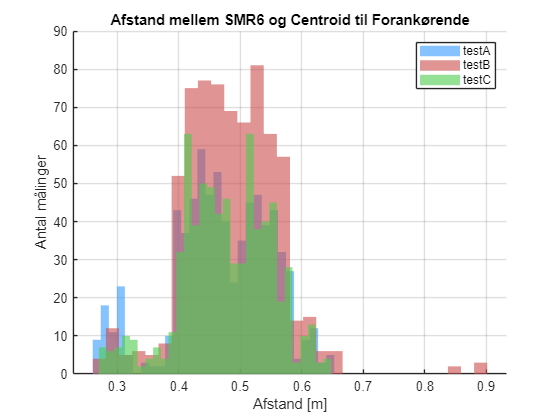

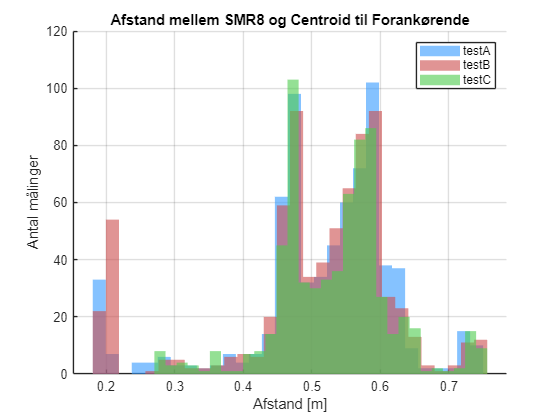

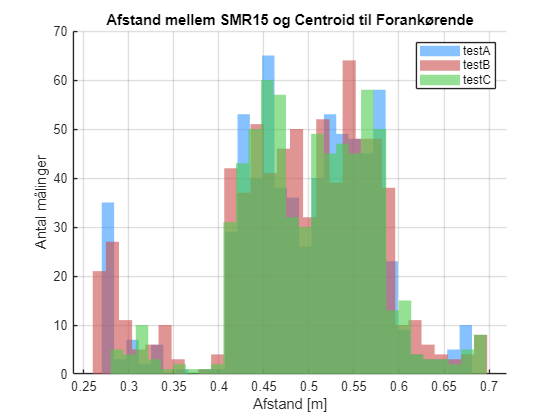

% --- Tests and SMR robots ---
tests = {'testA', 'testB', 'testC'};
robots = {'SMR6', 'SMR8', 'SMR15'};
colors = containers.Map(...
    {'testA', 'testB', 'testC'}, ...
    {[0.2 0.6 1.0], [0.8 0.3 0.3], [0.3 0.8 0.3]});

% --- Loop over each SMR robot ---
for r = 1:numel(robots)
    robot = robots{r};

    figure('Name', sprintf('%s → Centroid', robot), 'Color', 'w');
    hold on;

    for i = 1:numel(tests)
        test = tests{i};

        % Load data using dynamic field access
        log = AllData.(test).(robot).full;

        % Filter valid rows
        valid = ~(log.Distance == -1 | log.ClusterSize == -1 | ...
                 (log.Robot_X == 0 & log.Robot_Y == 0) | ...
                 log.Centroid_X == -1 | log.Centroid_X == -1000 | ...
                 log.Centroid_Y == -1 | log.Centroid_Y == -1000);
        log = log(valid, :);

        if height(log) < 2
            warning('Not enough data for %s in %s', robot, test);
            continue;
        end

        % Transform to global coordinates
        idx = find(log.Robot_X ~= 0 | log.Robot_Y ~= 0, 1);
        theta = deg2rad(log.Robot_Heading_deg(idx));
        R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
        v = R * [log.Centroid_X(idx); log.Centroid_Y(idx)];

        r = R * [log.Robot_X'; log.Robot_Y'];
        xg = r(1,:)' - v(1);
        yg = r(2,:)' - v(2);

        c = R * [log.Centroid_X'; log.Centroid_Y'];
        xc = c(1,:)' - v(1);
        yc = c(2,:)' - v(2);

        % Interpolate to shared time base
        N = min(length(xg), length(xc));
        t = linspace(0, 1, N);
        interp1_norm = @(x) interp1(linspace(0,1,length(x)), x, t, 'linear', 'extrap');

        xg_i = interp1_norm(xg);
        yg_i = interp1_norm(yg);
        xc_i = interp1_norm(xc);
        yc_i = interp1_norm(yc);

        % Compute error
        e = sqrt((xg_i - xc_i).^2 + (yg_i - yc_i).^2);

        % Plot histogram (not normalized!)
        histogram(e, 30, ...
            'Normalization', 'count', ...
            'DisplayName', test, ...
            'FaceColor', colors(test), ...
            'EdgeColor', 'none', ...
            'FaceAlpha', 0.6);
    end

    % Final plot formatting
    title(sprintf('Afstand mellem %s og Centroid til Forankørende', robot), 'FontWeight', 'bold');
    xlabel('Afstand [m]');
    ylabel('Antal målinger');
    legend('Location', 'northeast');
    grid on;
end

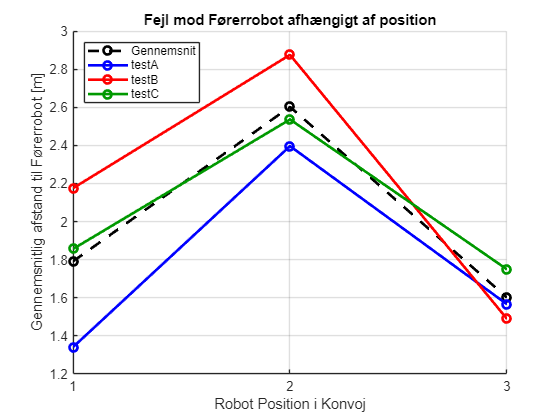











% --- Add Robot IDs ---
T1.Robot = repmat("SMR6", height(T1), 1);
T2.Robot = repmat("SMR6", height(T2), 1);
T3.Robot = repmat("SMR6", height(T3), 1);
results_SMR15_to_11.Robot       = repmat("SMR15", height(results_SMR15_to_11), 1);
results_Centroid_to_8.Robot     = repmat("SMR15", height(results_Centroid_to_8), 1);
results_SMR15_to_Centroid.Robot = repmat("SMR15", height(results_SMR15_to_Centroid), 1);
results_SMR8_to_11.Robot        = repmat("SMR8", height(results_SMR8_to_11), 1);
results_Centroid_to_11.Robot    = repmat("SMR8", height(results_Centroid_to_11), 1);
results_SMR8_to_Centroid.Robot  = repmat("SMR8", height(results_SMR8_to_Centroid), 1);

% --- Stack corresponding tables ---
T1_all = [results_SMR8_to_11; results_SMR15_to_11; T1];  % Robot → Leader
T2_all = [results_Centroid_to_11; results_Centroid_to_8; T2];  % Centroid → Robot Ahead
T3_all = [results_SMR8_to_Centroid; results_SMR15_to_Centroid; T3];  % Robot → Centroid


function plot_metric_band(T, title_str)
    robot_order = ["SMR8", "SMR15", "SMR6", "Gennemsnit"];
    robot_x_map = containers.Map(robot_order, 1:4);
    test_colors = containers.Map({'testA', 'testB', 'testC', 'Gennemsnit'}, ...
                                 {[0 0 1], [1 0 0], [0 0.6 0], [0 0 0]});
    line_style_map = containers.Map({'testA', 'testB', 'testC', 'Gennemsnit'}, ...
                                    {'-o','-o','-o','--o'});

    figure('Color','w'); hold on;
    tests = unique(T.Test);

    for k = 1:length(tests)
        tname = tests{k};
        idx = strcmp(T.Test, tname);
        x = arrayfun(@(r) robot_x_map(r), T.Robot(idx));
        y = T.MeanErr(idx);

        % --- Plot line only ---
        plot(x, y, line_style_map(tname), ...
            'Color', test_colors(tname), ...
            'LineWidth', 2, ...
            'DisplayName', tname);
    end

    xticks(1:3);
    xticklabels({'1','2','3'});
    xlabel('Robot Position i Konvoj');
    ylabel('Gennemsnitlig afstand til Førerrobot [m]');
    title(title_str, 'FontWeight', 'bold');
    legend('Location','northwest');
    grid on;
end



plot_metric_band(T1_all, 'Fejl mod Førerrobot afhængigt af position');

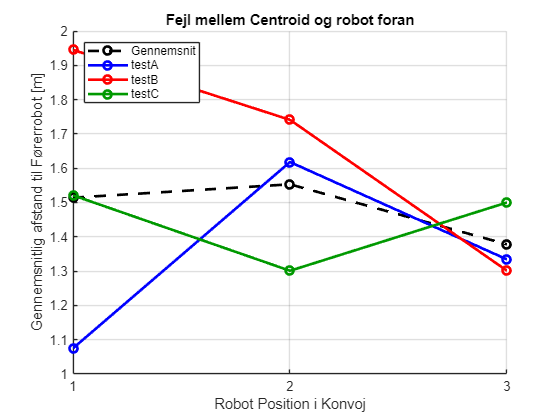

plot_metric_band(T2_all, 'Fejl mellem Centroid og robot foran');

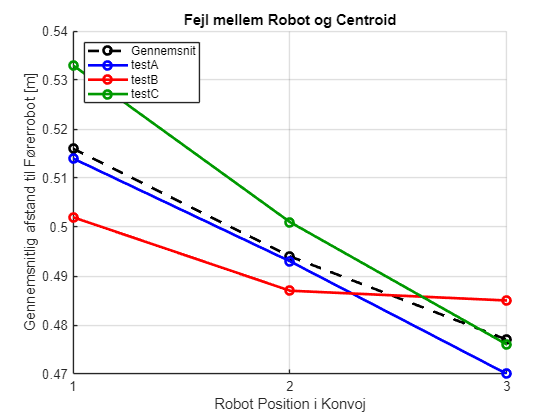

plot_metric_band(T3_all, 'Fejl mellem Robot og Centroid');

## Test of SMR 15, 6, 8

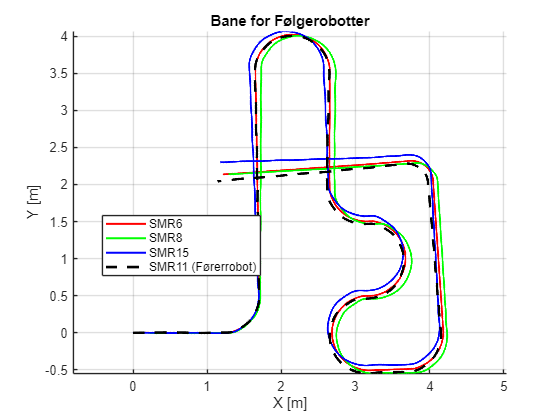

% --- Setup ---
base_path = 'C:\Users\Markus\Desktop\test of SMR';
robots = [6, 8, 15];
colors = containers.Map([6, 8, 15], {[1 0 0], [0 1 0], [0 0 1]});
styles = containers.Map([6, 8, 15], {'-', '-', '-'});

% --- Load leader trajectory (SMR11) ---
file11 = fullfile(base_path, 'log11');
if ~isfile(file11)
    error('Missing SMR11 log!');
end
R11 = readmatrix(file11);
x11 = R11(:,1); y11 = R11(:,2);

% --- Load and store data ---
data = struct();
for id = robots
    file = fullfile(base_path, sprintf('log%d', id));
    if isfile(file)
        raw = readmatrix(file);
        data.(sprintf('SMR%d', id)).x = raw(:,1);
        data.(sprintf('SMR%d', id)).y = raw(:,2);
        data.(sprintf('SMR%d', id)).t = raw(:,5);
    else
        warning('Missing log for SMR%d', id);
    end
end

% --- Plot follower trajectories ---
figure; hold on; grid on;
for id = robots
    R = data.(sprintf('SMR%d', id));
    plot(R.x, R.y, styles(id), 'Color', colors(id), ...
        'DisplayName', sprintf('SMR%d', id), 'LineWidth', 1.5);
end
plot(x11, y11, 'k--', 'DisplayName', 'SMR11 (Førerrobot)', 'LineWidth', 2);
xlabel('X [m]'); ylabel('Y [m]');
title('Bane for Følgerobotter');
legend('Location', 'best');
axis equal;


% --- Distance Error Metrics: Robot → Leader (SMR11) ---
disp('=== Distance Errors: Robot → SMR11 (Førerrobot) ===');

=== Distance Errors: Robot → SMR11 (Førerrobot) ===


results_robot_to_leader = [];
for id = robots
    R = data.(sprintf('SMR%d', id));
    N = min(length(R.x), length(x11));
    t = linspace(0, 1, N);
    xi = interp1(linspace(0,1,length(R.x)), R.x, t);
    yi = interp1(linspace(0,1,length(R.y)), R.y, t);
    x11i = interp1(linspace(0,1,length(x11)), x11, t);
    y11i = interp1(linspace(0,1,length(y11)), y11, t);
    e = sqrt((xi - x11i).^2 + (yi - y11i).^2);
    results_robot_to_leader = [results_robot_to_leader; ...
        {sprintf('SMR%d', id), round(mean(e),3), round(std(e),3), ...
         round(min(e),3), round(max(e),3), round(median(e),3)}];
end
T1 = cell2table(results_robot_to_leader, ...
    'VariableNames', {'Robot', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr'});
disp(T1);

      Robot      MeanErr    StdErr    MinErr    MaxErr    MedianErr
    _________    _______    ______    ______    ______    _________

    {'SMR6' }     0.041     0.032       0       0.118       0.038  
    {'SMR8' }     0.093     0.049       0       0.184       0.101  
    {'SMR15'}     0.134     0.091       0       0.322       0.114  




% --- Placeholders for other analysis types ---
% e.g., Centroid → Robot in Front, Robot → Centroid
% You should merge in the values from your previous `T2_all`, `T3_all` if available
% Or replace this with T2_all, T3_all visualization if already computed

% --- Summary ---
disp('Done plotting and computing Robot → SMR11 distance error.');

Done plotting and computing Robot → SMR11 distance error.


## Centroid consitency

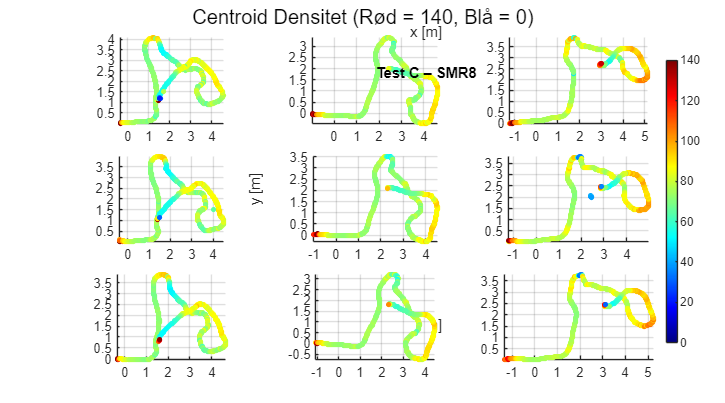

clc;

tests = {'testA', 'testB', 'testC'};
test_labels = {'Test A', 'Test B', 'Test C'};
robots = {'SMR8', 'SMR15', 'SMR6'};  % <-- NEW ORDER
d_follow = 0.28;

figure('Name', 'Centroid ClusterSize Heatmap (3x3)', 'Position', [100, 100, 1800, 1000]);
sgtitle('Centroid Densitet (Rød = 140, Blå = 0)');

centroids_x = cell(3,3);
centroids_y = cell(3,3);
cluster_vals = cell(3,3);
axs = gobjects(3,3);

for i = 1:3  % tests
    test = tests{i};

    % Raw logs for origin reference
    raw11 = AllData.(test).SMR11.raw;
    full_log8 = AllData.(test).SMR8.full;
    full_log15 = AllData.(test).SMR15.full;
    full_log6 = AllData.(test).SMR6.full;

    % --- SMR11 reference origin ---
    x11 = raw11(:,1); y11 = raw11(:,2);
    valid11 = ~(x11 == 0 & y11 == 0);
    idx11 = find(valid11, 1, 'first');
    origin11 = [x11(idx11); y11(idx11)];

    % --- SMR8 anchor ---
    idx8 = find(full_log8.Robot_X ~= 0 | full_log8.Robot_Y ~= 0, 1, 'first');
    R8 = rotmat(full_log8.Robot_Heading_deg(idx8));
    r8 = R8 * [full_log8.Robot_X(idx8); full_log8.Robot_Y(idx8)];
    c8 = R8 * [full_log8.Centroid_X(idx8); full_log8.Centroid_Y(idx8)];
    anchor8 = r8 - c8 + origin11;

    % --- SMR15 anchor ---
    idx15 = find(full_log15.Robot_X ~= 0 | full_log15.Robot_Y ~= 0, 1, 'first');
    R15 = rotmat(full_log15.Robot_Heading_deg(idx15));
    h15 = headingvec(full_log15.Robot_Heading_deg(idx15));
    r15 = R15 * [full_log15.Robot_X(idx15); full_log15.Robot_Y(idx15)];
    c15 = R15 * [full_log15.Centroid_X(idx15); full_log15.Centroid_Y(idx15)];
    anchor15 = r15 - c15 + anchor8 - d_follow * h15;

    % --- SMR6 anchor ---
    idx6 = find(full_log6.Robot_X ~= 0 | full_log6.Robot_Y ~= 0, 1, 'first');
    R6 = rotmat(full_log6.Robot_Heading_deg(idx6));
    h6 = headingvec(full_log6.Robot_Heading_deg(idx6));
    c6 = R6 * [full_log6.Centroid_X(idx6); full_log6.Centroid_Y(idx6)];
    anchor6 = anchor15 - d_follow * h6;

    % --- Loop over robots in NEW ORDER ---
    for j = 1:3
        robot = robots{j};
        full_log = AllData.(test).(robot).full;

        % Remove invalid
        valid = full_log.ClusterSize ~= -1 & ...
                full_log.Centroid_X ~= 0 & full_log.Centroid_Y ~= 0 & ...
                full_log.Robot_X ~= 0 & full_log.Robot_Y ~= 0;
        if sum(valid) < 10, continue; end

        cx = full_log.Centroid_X(valid);
        cy = full_log.Centroid_Y(valid);
        clusterSize = full_log.ClusterSize(valid);

        % Global transform using fixed R and anchor
        switch robot
            case 'SMR6'
                R = R6; anchor = anchor6; c_start = c6;
            case 'SMR15'
                R = R15; anchor = anchor15; c_start = c15;
            case 'SMR8'
                R = R8; anchor = anchor8; c_start = c8;
        end

        centroid_local = [cx'; cy'];
        centroid_rotated = R * centroid_local;
        xg = centroid_rotated(1,:)' - c_start(1) + anchor(1);
        yg = centroid_rotated(2,:)' - c_start(2) + anchor(2);

        centroids_x{i,j} = xg;
        centroids_y{i,j} = yg;
        cluster_vals{i,j} = clusterSize;
    end
end

% --- Plotting ---
for i = 1:3
    for j = 1:3
        if isempty(centroids_x{i,j}), continue; end
        axs(i,j) = subplot(3, 3, (i-1)*3 + j);
        scatter(centroids_x{i,j}, centroids_y{i,j}, 15, cluster_vals{i,j}, 'filled');
        title(sprintf('%s – %s', test_labels{i}, robots{j}), 'Interpreter', 'none');
        xlabel('x [m]'); ylabel('y [m]');
        axis equal tight; grid on;
    end
end

% --- Shared colorbar ---
colormap(jet);  % Red = 140, Blue = 0
cmin = 0; cmax = 140;
for k = 1:numel(axs)
    if isgraphics(axs(k))
        caxis(axs(k), [cmin cmax]);
    end
end

cb = colorbar('Position', [0.92 0.15 0.015 0.7]);
cb.Label.String = 'Cluster Densitet';
cb.Label.FontSize = 12;


% --- Helpers ---
function R = rotmat(deg)
    theta = deg2rad(deg);
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
end

function h = headingvec(deg)
    theta = deg2rad(deg);
    h = [cos(theta); -sin(theta)];
end

